## Data

clear all; close all; clc;
set_env;
more_plots = 0;

% Data --------------------------------------------------------------
% Constants
eps_0 = 8.85e-12; 			% F/m , permittivity of vacuum
epsilon1_max = 0.05;

% Symbolic variables ------------------------------------------------
% Physical properties
syms nu Y_p epsilon_p epsilon_f EBD_p EBD_f real positive

% Geometry of the capacitor
syms x l_0 w_0 tp_0 xi xi_0 tf_0 dt_f dtf real positive
% t_f(x) armature distance at a certain xsi

% Physical quantities
syms Uel(x) V F(x,V) C(x)
% 
% % Strains: eps1 along the polymer, eps3 thickness strain of the polymer

syms epsilon_1(x) epsilon_2(x) epsilon_3(x)


## Equations

syms eps1 eps2 eps3 s1 s2 s3

% Equations ---------------------------------------------------------
eqstrain = [
eps1 == 1 / Y_p * (s1 - nu * (s2 + s3)),...
eps2 == 1 / Y_p * (s2 - nu * (s1 + s3)),...
eps3 == 1 / Y_p * (s3 - nu * (s1 + s2))
]

$$eqstrain = \left(\begin{array}{ccc} {\mathrm{eps}}_{1}=\frac{s_{1}-\nu \,\left(s_{2}+s_{3}\right)}{Y_{p}} & {\mathrm{eps}}_{2}=\frac{s_{2}-\nu \,\left(s_{1}+s_{3}\right)}{Y_{p}} & {\mathrm{eps}}_{3}=\frac{s_{3}-\nu \,\left(s_{1}+s_{2}\right)}{Y_{p}} \end{array}\right)$$


soldef = solve(subs(eqstrain, {eps2,s3}, {0,0}), [s1, s2, eps3])

soldef = struct with fields:
      s1: -(Y_p*eps1)/(nu^2 - 1)
      s2: -(Y_p*eps1*nu)/(nu^2 - 1)
    eps3: (eps1*nu)/(nu - 1)


sigma_1 = subs(soldef.s1, eps1, epsilon_1);

clear eps1 eps2 eps3 s1 s2 s3


% Geometry ------------------------------
l(x) = l_0 * (1 + epsilon_1(x));
t_p(x) = tp_0 * (1 + epsilon_3(x));
w = w_0;
dt_f(x) = simplify(solve((x/2 - tf_0 / 2) / l_0 == (dtf / 2) / (l_0 - (xi - xi_0)), dtf), 25)

$$dt\_f(x) = -\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)}{l_{0}}$$

t_f(x) = tf_0 + dt_f; 
A = l * w;
dA = w * (1 + epsilon_1(x)) ; % * dxi

% Range limit
x_min = sdata(tf_0)

$$x\_min = \frac{1}{10000}$$

x_max = rhs(isolate(sstrain(epsilon_1(x)) == epsilon1_max, x))

$$x\_max = {\mathrm{tf}}_{0}+\frac{\sqrt{41}\,l_{0}}{10}$$


% Polymer infinitesimal capacitance
dCp = dA * epsilon_p / t_p

$$dCp(x) = \frac{\epsilon_{p}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}$$

% Fluid infinitesimal capacitance
dCf = dA * epsilon_f / t_f

$$dCf(x) = \frac{\epsilon_{f}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)}{l_{0}}}$$


% Total infinitesimal capacitance
dC = ((2 / dCp) + (1 / dCf))^(-1)

$$dC(x) = \frac{1}{\frac{{\mathrm{tf}}_{0}-\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)}{l_{0}}}{\epsilon_{f}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)}+\frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}{\epsilon_{p}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)}}$$

## Capacitance

% Total capacitance +++++++++++++++++++++++++++++++++++++++++++++++++
C(x) = int(dC, xi)

$$C(x) = \frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(\epsilon_{p}\,\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-x}$$

C(x) = subs(C(x), xi, xi_0 + l_0) - subs(C(x), xi, xi_0)

$$C(x) = \frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-x}-\frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(\epsilon_{p}\,l_{0}\,\left({\mathrm{tf}}_{0}-x\right)-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-x}$$

CC(x) = sstrain(C);
Cplane = simplify(limit(CC, x, tf_0))

$$Cplane = \frac{\epsilon_{f}\,\epsilon_{p}\,l_{0}\,w_{0}}{\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}}$$

C(x) = piecewise(x <= tf_0+1e-10, Cplane, x > tf_0+1e-10, CC(x))

$$C(x) = \left\{ \begin{array}{cl} \frac{\epsilon_{f}\,\epsilon_{p}\,l_{0}\,w_{0}}{\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}} & \text{ if }x\leq {\mathrm{tf}}_{0}+\frac{1}{10000000000}\\ \frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-\frac{2\,\epsilon_{f}\,l_{0}\,\nu \,{\mathrm{tp}}_{0}\,\left(\sqrt{\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{4\,{l_{0}}^{2}}+1}-1\right)}{\nu -1}\right)\,\sqrt{\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{4\,{l_{0}}^{2}}+1}}{{\mathrm{tf}}_{0}-x}-\frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(\epsilon_{p}\,l_{0}\,\left({\mathrm{tf}}_{0}-x\right)-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-\frac{2\,\epsilon_{f}\,l_{0}\,\nu \,{\mathrm{tp}}_{0}\,\left(\sqrt{\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{4\,{l_{0}}^{2}}+1}-1\right)}{\nu -1}\right)\,\sqrt{\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{4\,{l_{0}}^{2}}+1}}{{\mathrm{tf}}_{0}-x} & \text{ if }{\mathrm{tf}}_{0}+\frac{1}{10000000000}<x \end{array}\right.$$


% Min capacitance
Cmin = vpa(subs(sdata(C), x, sdata(x_max)), 4)

$$Cmin(x) = 1.864e-11$$


% Max C
Cmax = sdata(Cplane)

$$Cmax = \frac{860832138089938872349005788615425}{2013196290598431521688765839982841871466496}$$

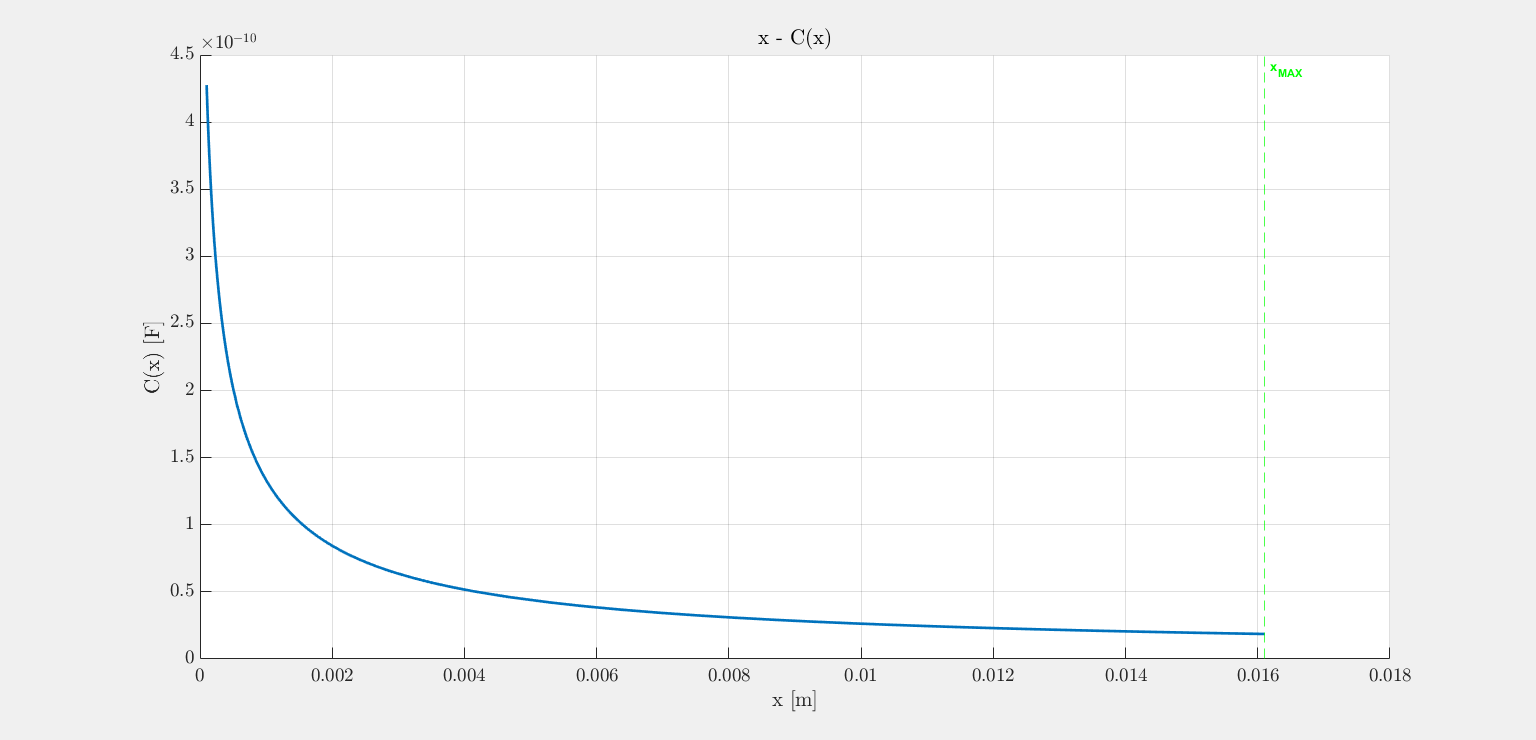

% Plot x - C(x)
myfig(1,"x - C(x)");
hold on
fplot(x, sdata(C(x)), [double(sdata(x_min)), double(sdata(x_max))], 'LineWidth', 2)
xline(double(sdata(x_max)), "--g", "x_{MAX}",'LabelOrientation','horizontal', 'FontWeight','bold')
hold off
title("x - C(x)")
xlabel("x [m]")
ylabel("C(x) [F]")

## Max voltage

% Max voltage
% Vmax(x) = A / C * min(epsilon_p * EBD_p, epsilon_f * EBD_f)
Vmax(x) = 2 * t_p / epsilon_p * min(epsilon_p * EBD_p, epsilon_f * EBD_f)

% Plot x - Vmax(x)
myfig(2,"x - Vmax(x)");
fplot(x, sdata(Vmax(x), 1), [sdata(x_min), sdata(x_max)], 'LineWidth', 2)
title("$x - V_{max}(x)$")
xlabel("x [m]")
ylabel("$V_{max}$(x) [V]")


## Force

% Force
Uel(x) = 2 * sdata(1 / 2 * (sigma_1 * epsilon_1) * w * t_p * l, 1)
F(x,V) = simplify(diff(Uel, x) - V^2 / 2 * diff(sdata(C, 1), x),100)

% Min and max force for V = 0 and V = Vmax
FVmin = vpa(F(x, 0), 4);
FVmax= vpa(F(x, sdata(Vmax, 1)), 4);

% Plot x - F(x)
xstart = sdata(x_min);
x_range = double(xstart:0.5e-4:sdata(x_max));

FVmin_vec = double(subs(FVmin,x_range));
FVmax_vec = double(subs(FVmax,x_range));
FVmax_vec = FVmax_vec(FVmax_vec < 40)
[fvmax_peak, idx] = findpeaks(real(FVmax_vec)) 
x_range = x_range(idx:end);
FVmax_vec = FVmax_vec(idx:end && FVmax_vec < 40);
FVmin_vec = FVmin_vec(idx:end);

Uel_Fx = double(trapz(x_range, FVmax_vec) - trapz(x_range, FVmin_vec))

myfig(3,"x - F(x)")
hold on
plot(x_range, FVmin_vec,'LineWidth', 1.5)
plot(x_range, FVmax_vec,'--', 'LineWidth', 1.5)
xline(x_range(end), "--g", "x_{MAX}",'LabelOrientation','horizontal', 'FontName', 'times new roman', 'FontWeight','bold')
xline(x_range(1), "--g", "x_{START}",'LabelOrientation','horizontal', 'FontName', 'times new roman', 'FontWeight','bold')
hold off
legend(["$V_{min}$", "$V_{max}$"], "Location", "north")
title("x - F(x)")
xlabel("x [m]")
ylabel("F(x) [N]")


## Q - V

% Plot Q - V
C_vec = double(sdata(C, 1, x, x_range));
Vmax_vec = double(sdata(Vmax, 1, x, x_range));
Vtmp = linspace(0, max(Vmax_vec), 100);
Q_vec = C_vec .* Vmax_vec;

Qmin = Vtmp * Cmin;
Qmax = Vtmp * Cmax;
V_maxstr = Q_vec ./ Cmin;
[V_maxstr_min, idx] = min(V_maxstr);
x_min_maxstr = x_range(idx);

V_minstr = Q_vec ./ Cmax;
[V_minstr_min, idx] = min(V_minstr);
x_min_minstr = x_range(idx);

Uel_QV = trapz(Q_vec, Vmax_vec) - trapz(Q_vec, V_minstr)
(V_minstr_min - Vmax_vec(end)) * (Q_vec(end) - Q_vec(1)) / 2

myfig(4,"Q - V"); clf
hold on
plot(Q_vec, Vmax_vec, 'DisplayName', "Voltage breakdown", "LineWidth", 1.5)
plot(Qmax, Vtmp, 'DisplayName', "Min. stretch", "LineWidth", 1.5)
plot(Qmin, Vtmp, 'DisplayName', "Max. stretch", "LineWidth", 1.5)
legend('Location','best')
xlabel("Q [A]")
ylabel("V [V]")
ylim([0,double(max(Vmax_vec))])
title("Q - V")
hold off























